# PRÁCTICA 1 - DETECCIÓN AUTOMÁTICA DE EQUIPOS DE FUTBOL EN IMÁGENES

#### Tips:

- Histograma 3-dimensional (con tripletas, no histograma 3D)

- Reducir los colores: Cada 4, 8 16 niveles de rojo, azul, verde => Para que coincidan los histogramas.

- Se puede aplicar normalización de color => Obtenemos una aplicaicón más tolerante a cambios de color y nos podemos cargar una componente => Histograma bidimensional.

syms R G B
r = R/(R+G+B)
g = G/(R+G+B)
b = B/(R+G+B)

## Image Model

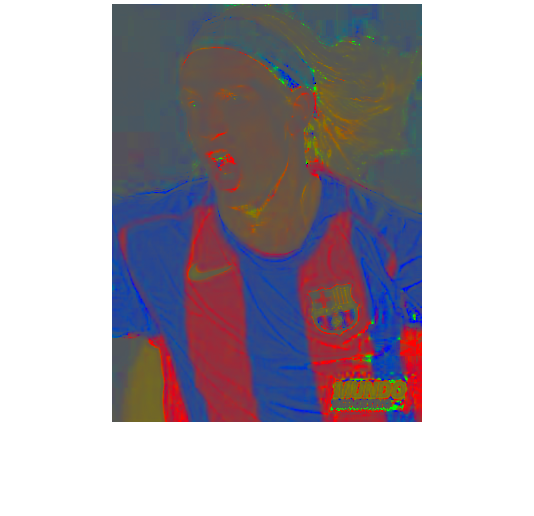

imageModel = imagePreProcessing(imread('./soccer/barcelona/05.jpg'));
plotHistogramAndImage(imageModel);

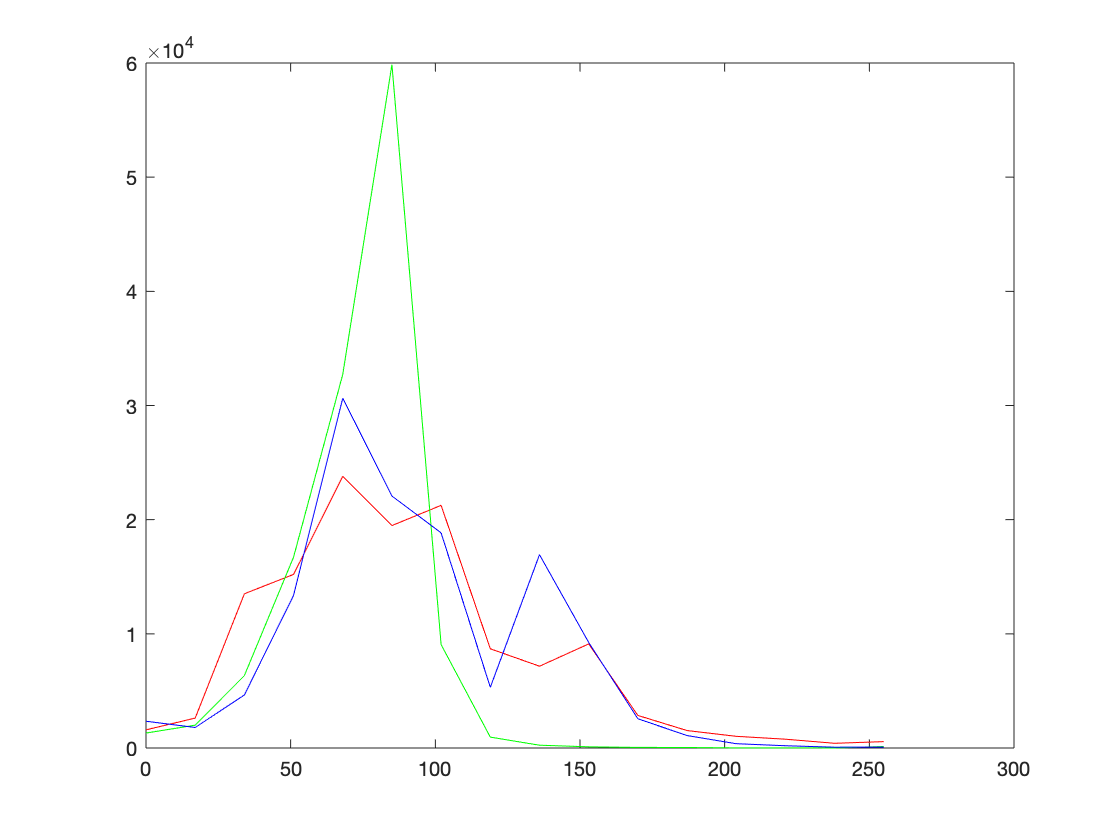

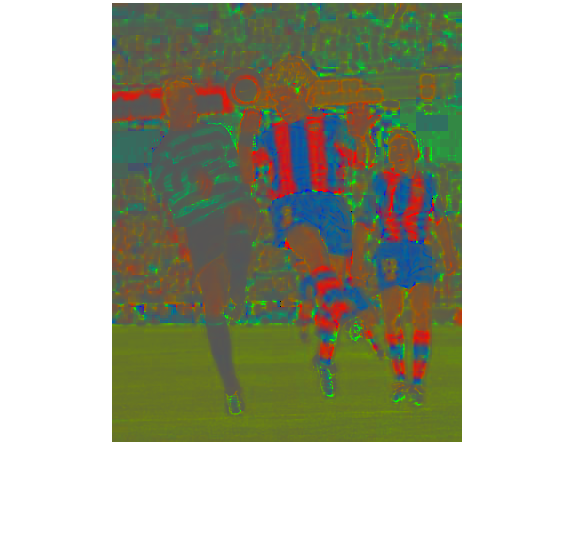

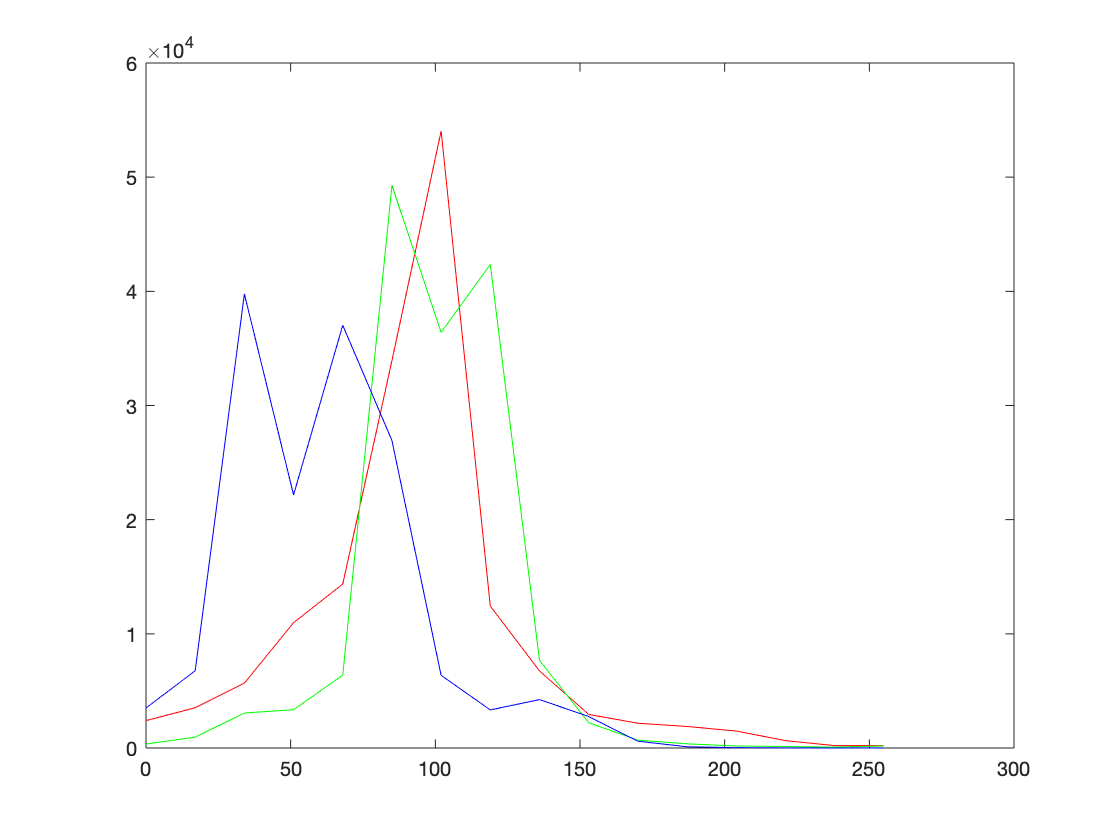


imageModel = imagePreProcessing(imread('./soccer/barcelona/10.jpg'));
plotHistogramAndImage(imageModel)

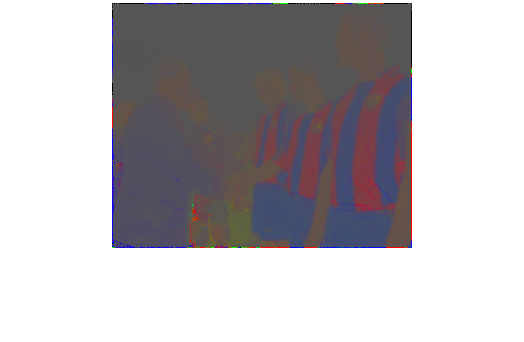

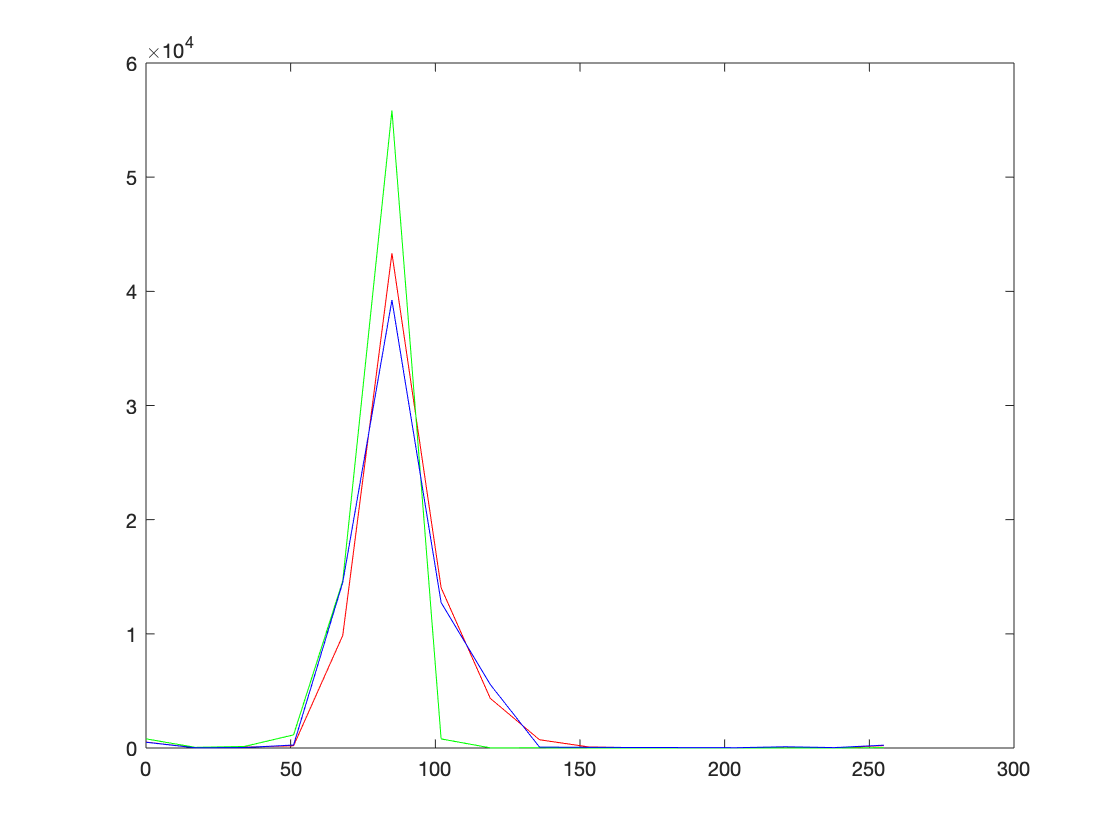


imageModel = imagePreProcessing(imread('./soccer/barcelona/12.jpg'));
plotHistogramAndImage(imageModel)

## Functions

function impp = imagePreProcessing(im)
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    
    I = double(r) + double(g) + double(b);
    Rn = double(r) ./ I;
    Gn = double(g) ./ I;
    Bn = double(b) ./ I;
    
    impp = uint8(cat(3, Rn, Gn, Bn) * 255);
end


function v = plotHistogramAndImage(im)
    figure;
    imshow(im);
    h = imhist(im);

    R = im(:,:,1);
    G = im(:,:,2);
    B = im(:,:,3);
    
    [yRed x] = imhist(R, 16);
    [yGreen x] = imhist(G, 16);
    [yBlue x] = imhist(B, 16);
    
    figure;
    plot(x, yRed, 'R', x, yGreen, 'G', x, yBlue, 'B');
    
end